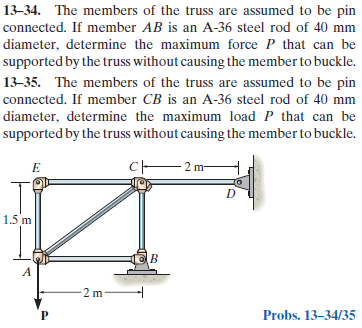

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-34P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-34P-solution-9780136022305) (problem 13-34)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-35P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-13-problem-35P-solution-9780136022305) (problem 13-35)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

Pvar = sym('P', 'positive');
theta = atand(sym(1.5)/sym(2))*u.deg;
jointA = [0 0]*u.m;
jointB = [2 0]*u.m;
jointC = [2 1.5]*u.m;
jointD = [4 1.5]*u.m;
jointE = [0 1.5]*u.m;

# member data

[D.ab D.bc] = deal(rewrite(40*u.mm, u.m));
[E.ab E.bc] = deal(rewrite(200*u.GPa, u.kN/u.m^2));
[A.ab A.bc] = deal(sympi*D.ab^2/4, sympi*D.bc^2/4);
[I.ab I.bc] = deal(sympi*(D.ab/2)^4/4, sympi*(D.bc/2)^4/4);
[L.ab L.bc] = deal(2*u.m, 1.5*u.m);
[sigma_yield.ab sigma_yield.bc] = deal(250*u.MPa);
Evar = sym('E');
Avar = sym('A');

# truss

t = Truss;
t = t.add('reaction', 'Rb', {'Rbx' 'Rby'}, jointB);
t = t.add('reaction', 'Rd', {'Rdx' 'Rdy'}, jointD);
t = t.add('concentrated', 'Pa', [0 -Pvar], jointA);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('joint', 'E', jointE);
t = t.add('member', 'Fab', jointA, jointB, E.ab, A.ab);
t = t.add('member', 'Fac', jointA, jointC);
t = t.add('member', 'Fae', jointA, jointE);
t = t.add('member', 'Fbc', jointB, jointC, E.bc, A.bc);
t = t.add('member', 'Fcd', jointC, jointD);
t = t.add('member', 'Fce', jointC, jointE);

# solution

[us ua ms ma ls la] = t.solve('factor');
[E.ab E.bc] = deal(rewrite(E.ab, u.GPa), rewrite(E.bc, u.GPa));
[A.ab A.bc] = deal(rewrite(A.ab, u.mm), rewrite(A.bc, u.mm));
[I.ab I.bc] = deal(rewrite(I.ab, u.mm), rewrite(I.bc, u.mm));
[D.ab D.bc] = deal(rewrite(D.ab, u.mm), rewrite(D.bc, u.mm));

# joint displacements

ua

$$ua = \left(\begin{array}{cc} \mathrm{uA} & \frac{P}{30000\,\pi }\,\frac{m}{\mathrm{kN}}\\ \mathrm{vA} & -\frac{7\,P\,\left(2160000\,\pi \,\mathrm{kN}+13\,A\,\text{E}\right)}{1440000\,A\,\text{E}\,\pi }\,\frac{m}{\mathrm{kN}}\\ \mathrm{uB} & 0\\ \mathrm{vB} & 0\\ \mathrm{uC} & -\frac{8\,P}{3\,A\,\text{E}}\,m\\ \mathrm{vC} & -\frac{3\,P}{160000\,\pi }\,\frac{m}{\mathrm{kN}}\\ \mathrm{uD} & 0\\ \mathrm{vD} & 0\\ \mathrm{uE} & -\frac{8\,P}{3\,A\,\text{E}}\,m\\ \mathrm{vE} & -\frac{7\,P\,\left(2160000\,\pi \,\mathrm{kN}+13\,A\,\text{E}\right)}{1440000\,A\,\text{E}\,\pi }\,\frac{m}{\mathrm{kN}} \end{array}\right)$$

# forces on the truss

ma_f_m = ma.f.m %#ok<NASGU> 

$$ma\_f\_m = \left(\begin{array}{cc} \mathrm{Fab} & -\frac{4\,P}{3}\\ \mathrm{Fac} & \frac{5\,P}{3}\\ \mathrm{Fae} & 0\\ \mathrm{Fbc} & -P\\ \mathrm{Fcd} & \frac{4\,P}{3}\\ \mathrm{Fce} & 0 \end{array}\right)$$

la_f_c = la.f.c %#ok<NASGU> 

$$la\_f\_c = \left(\begin{array}{cccc} \mathrm{Rb} & -\frac{4\,P}{3} & P & 0\\ \mathrm{Rd} & \frac{4\,P}{3} & 0 & 0\\ \mathrm{Pa} & 0 & -P & 0 \end{array}\right)$$

ma_f_c = ma.f.c %#ok<NASGU> 

$$ma\_f\_c = \left(\begin{array}{cccc} \mathrm{Fab} & -\frac{4\,P}{3} & 0 & 0\\ \mathrm{Fac} & \frac{4\,P}{3} & P & 0\\ \mathrm{Fae} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & -P & 0\\ \mathrm{Fcd} & \frac{4\,P}{3} & 0 & 0\\ \mathrm{Fce} & 0 & 0 & 0 \end{array}\right)$$

la_f_m = la.f.m %#ok<NASGU> 

$$la\_f\_m = \left(\begin{array}{cc} \mathrm{Rb} & \frac{5\,P}{3}\\ \mathrm{Rd} & \frac{4\,P}{3}\\ \mathrm{Pa} & P \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fac} & 0\\ \mathrm{Fae} & 0\\ \mathrm{Fbc} & 2\,P\,m\\ \mathrm{Fcd} & 2\,P\,m\\ \mathrm{Fce} & 0 \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Rb} & 0 & 0 & 2\,P\,m\\ \mathrm{Rd} & 0 & 0 & -2\,P\,m\\ \mathrm{Pa} & 0 & 0 & 0 \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fac} & 0 & 0 & 0\\ \mathrm{Fae} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & -2\,P\,m\\ \mathrm{Fcd} & 0 & 0 & -2\,P\,m\\ \mathrm{Fce} & 0 & 0 & 0 \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Rb} & 2\,P\,m\\ \mathrm{Rd} & 2\,P\,m\\ \mathrm{Pa} & 0 \end{array}\right)$$

# maximum load due to buckling

Pcr.buckling.ab = rewrite(sympi^2*E.ab*I.ab/L.ab^2, u.kN);
Pcr.buckling.bc = rewrite(sympi^2*E.bc*I.bc/L.bc^2, u.kN);
Pcr_buckling_ab = vpa(Pcr.buckling.ab, 4) %#ok<NASGU> 

$$Pcr\_buckling\_ab = 62.01\,\mathrm{kN}$$

Pcr_buckling_bc = vpa(Pcr.buckling.bc, 5) %#ok<NASGU> 

$$Pcr\_buckling\_bc = 110.24\,\mathrm{kN}$$

Pmax.buckling.ab = solve(abs(ms.f.m.Fab) == Pcr.buckling.ab);
Pmax.buckling.bc = solve(abs(ms.f.m.Fbc) == Pcr.buckling.bc);
Pmax_buckling_ab = vpa(Pmax.buckling.ab, 4) %#ok<NASGU> 

$$Pmax\_buckling\_ab = 46.51\,\mathrm{kN}$$

Pmax_buckling_bc = vpa(Pmax.buckling.bc, 5) %#ok<NASGU> 

$$Pmax\_buckling\_bc = 110.24\,\mathrm{kN}$$

# maximum load due to yield

Pcr.yield.ab = rewrite(solve(sigma_yield.ab == Pvar/A.ab), u.kN);
Pcr.yield.bc = rewrite(solve(sigma_yield.bc == Pvar/A.bc), u.kN);
Pcr_yield_ab = vpa(Pcr.yield.ab, 5) %#ok<NASGU> 

$$Pcr\_yield\_ab = 314.16\,\mathrm{kN}$$

Pcr_yield_bc = vpa(Pcr.yield.ab, 5) %#ok<NASGU> 

$$Pcr\_yield\_bc = 314.16\,\mathrm{kN}$$

Pmax.yield.ab = solve(abs(ms.f.m.Fab) == Pcr.yield.ab);
Pmax.yield.bc = solve(abs(ms.f.m.Fbc) == Pcr.yield.bc); 
Pmax_yield_ab = vpa(Pmax.yield.ab, 5) %#ok<NASGU> 

$$Pmax\_yield\_ab = 235.62\,\mathrm{kN}$$

Pmax_yield_bc = vpa(Pmax.yield.bc, 5) %#ok<NASGU> 

$$Pmax\_yield\_bc = 314.16\,\mathrm{kN}$$

# clean up

clear ma_f_m la_f_c ma_f_c la_f_m;
clear ma_m_m la_m_c ma_m_c la_m_m;
clear Pcr_buckling_ab Pcr_buckling_bc Pmax_buckling_ab Pmax_buckling_bc;
clear Pcr_yield_ab Pcr_yield_bc Pmax_yield_ab Pmax_yield_bc;
new_assum = old_assum;